% Load training data.
data = load('');
trainData = data.trainData;

% Display dataset summary
summary(trainData)


Variables:

    wd: 1872×1 cell array of character vectors

    bbox: 1872×1 cell



% Combine all the ground truth boxes into one array.
allBoxes = vertcat(trainData.bbox{:});

 Plot the box area versus the box aspect ratio. 

% Plot the box area versus box aspect ratio.
dev = gpuDevice(2);
aspectRatio = allBoxes(:,3) ./ allBoxes(:,4);
area = prod(allBoxes(:,3:4),2);

figure

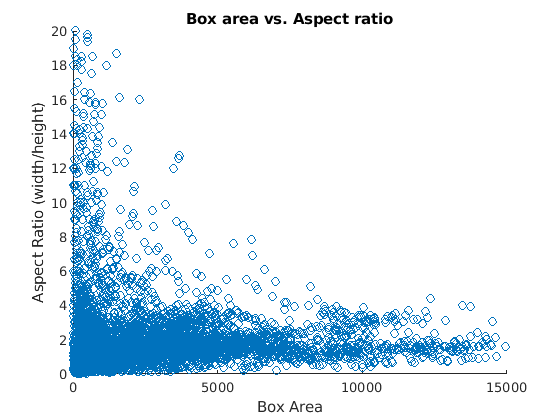

scatter(area,aspectRatio)
xlim([0 15000]) 
ylim([0 20])
xlabel("Box Area")
ylabel("Aspect Ratio (width/height)");
title("Box area vs. Aspect ratio")

Visually, you see a few groups of objects that are of similar size and shape, but the groups are spread out. This makes it difficult to manually choose anchor boxes. A better way to estimate anchor boxes is to use a clustering algorithm that can group similar boxes together using a meaningful metric.

## Cluster Ground Truth Boxes

Cluster the boxes using the `kmedoids` function with custom intersection-over-union (IoU) distance metric. Other clustering functions such as `clusterdata` or `dbscan` may also be used. 

A distance metric based on IoU is invariant to the size of boxes, unlike the Euclidean distance metric, which produces larger errors as the box sizes increase [1]. In addition, an IoU distance metric leads to boxes of similar aspect ratio and sizes being clustered together, which results in anchor box estimates that fit the data. The IoU distance metric is implemented in the supporting function, `iouDistanceMetric`.  

Select the number of anchors and estimate the anchor boxes using `kmedoids`. The cluster centers returned by `kmedoids` are the anchor box estimates. 

% Select the number of anchor boxes.
numAnchors = 6;

% Cluster using K-Medoids.
[clusterAssignments, anchorBoxes, sumd] = kmedoids(allBoxes(:,3:4),numAnchors,'Distance',@iouDistanceMetric);

% Display estimated anchor boxes. The box format is the [width height].
anchorBoxes

anchorBoxes =     49    39
    24    26
   101    68
    38    23
    21    16
    77    44


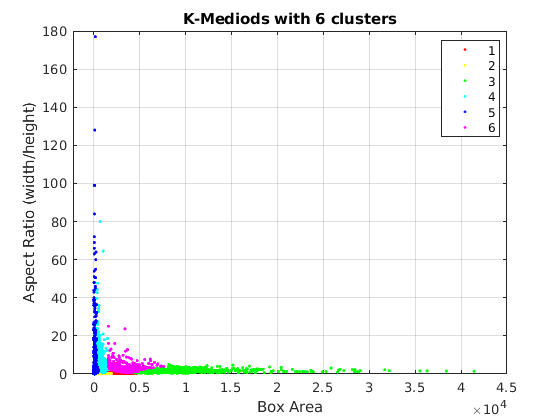

% Display clustering results.
figure
gscatter(area,aspectRatio,clusterAssignments);
title("K-Mediods with "+numAnchors+" clusters")
xlabel("Box Area")
ylabel("Aspect Ratio (width/height)");
grid

Choosing the number of anchors is another training hyperparameter that requires careful selection using empirical analysis. One quality measure for judging the estimated anchor boxes is the mean IoU of the boxes in each cluster. Calculate this using the cluster assignments produced by `kmedoids`.

% Count number of boxes per cluster. Exclude the cluster center while
% counting.
counts = accumarray(clusterAssignments, ones(length(clusterAssignments),1),[],@(x)sum(x)-1);

% Compute mean IoU.
meanIoU = mean(1 - sumd./(counts))

meanIoU = 0.6684

The mean IoU should be greater than 0.5 to ensure anchor boxes overlap well with the boxes in the training data. Increasing the number of anchors may improve the mean IoU measure. However, using more anchor boxes in an object detector may increase the computation cost and lead to overfitting, which results in poor detector performance. 

Sweep over a range of values and plot the mean IoU versus number of anchor boxes to measure the trade-off between number of anchors an mean IoU.

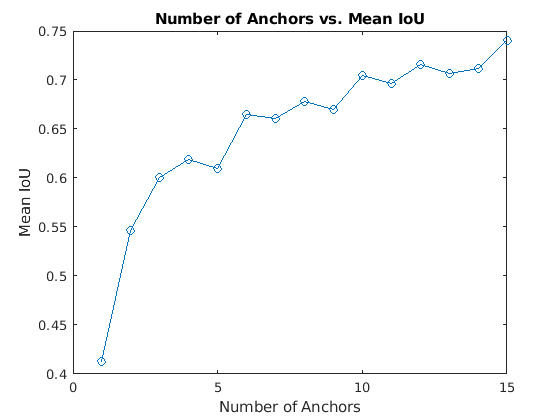

maxNumAnchors = 15;
for k = 1:maxNumAnchors
    
    % Estimate anchors using clustering.
    [clusterAssignments, anchorBoxes, sumd] = kmedoids(allBoxes(:,3:4),k,'Distance',@iouDistanceMetric);
    
    % Compute mean IoU.
    counts = accumarray(clusterAssignments, ones(length(clusterAssignments),1),[],@(x)sum(x)-1);
    meanIoU(k) = mean(1 - sumd./(counts));
end

figure
plot(1:maxNumAnchors, meanIoU,'-o')
ylabel("Mean IoU")
xlabel("Number of Anchors")
title("Number of Anchors vs. Mean IoU")

Two anchor boxes provide a mean IoU above 0.7 and there is marginal improvement in mean IoU beyond 6 anchor boxes. Given these results, the next step is to train and evaluate multiple object detectors using values between 2 and 6. This empirical analysis helps determine the number of anchor boxes required to satisfy application performance requirements such as detection speed or accuracy.

## References

- Redmon, Joseph, and Ali Farhadi. "YOLO9000: Better, Faster, Stronger." 2017 IEEE Conference on Computer Vision and Pattern Recognition (CVPR). IEEE, 2017.

## Supporting Functions

function dist = iouDistanceMetric(boxWidthHeight,allBoxWidthHeight)
% Return the IoU distance metric. The bboxOverlapRatio function
% is used to produce the IoU scores. The output distance is equal
% to 1 - IoU.

% Add x and y coordinates to box widths and heights so that
% bboxOverlapRatio can be used to compute IoU.
boxWidthHeight = prefixXYCoordinates(boxWidthHeight);
allBoxWidthHeight = prefixXYCoordinates(allBoxWidthHeight);

% Compute IoU distance metric.
dist = 1 - bboxOverlapRatio(allBoxWidthHeight, boxWidthHeight);
end

function boxWidthHeight = prefixXYCoordinates(boxWidthHeight)
% Add x and y coordinates to boxes.
n = size(boxWidthHeight,1);
boxWidthHeight = [ones(n,2) boxWidthHeight];
end

*Copyright 2018 The MathWorks, Inc.*